# 2-D Proportional Navigation (PN) — Live Script Wrapper

Single-core simulator: pn_2d_sim.m This Live Script configures scenarios, calls pn_2d_sim once per case, and renders all figures.

## User Parameters

SAVE_PLOT = 0;  % 1 to save PNGs

% Base scenario
s = struct();
s.dt = 0.01; s.Tmax = 240;
s.N0 = 10.0; s.a_max = 20; s.use_actuator = 1;

% Missile
s.m_pos0 = [0; 0];
s.m_vel0 = 300*[cosd(5); sind(5)];

% Target
s.t_pos0 = [6000; 2000];
s.t_vel0 = 250*[cosd(-10); sind(-10)];

% Target maneuver
s.t_maneuver_on  = 5;
s.t_maneuver_off = 25;
s.t_maneuver_acc = 20;

% Termination / estimates
s.r_impact_threshold = 5;
s.min_Vc_for_tgo     = 5;

## Run simulation (single case)

sim = pn_2d_sim(s);

if sim.impact
    fprintf('Intercept at t = %.3f s, final miss = %.3f m\n', sim.impact_time, sim.miss_distance);
else
    fprintf('No intercept. Final miss = %.3f m at t = %.3f s\n', sim.miss_distance, sim.t(end));
end

Intercept at t = 89.490 s, final miss = 4.312 m


## Plot: Trajectories

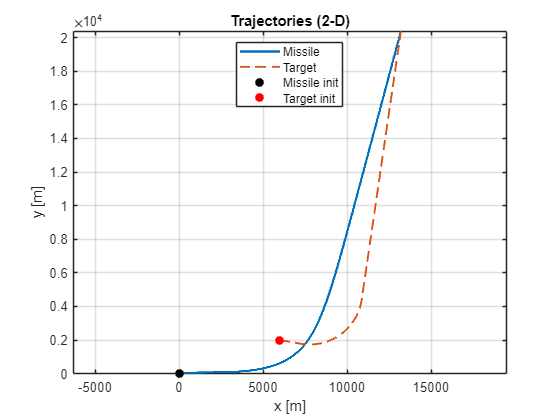

figure;
plot(sim.m_pos(1,:), sim.m_pos(2,:), '-', 'LineWidth', 1.8); hold on;
plot(sim.t_pos(1,:), sim.t_pos(2,:), '--', 'LineWidth', 1.4);
plot(sim.m_pos(1,1), sim.m_pos(2,1), 'ko','MarkerFaceColor','k');
plot(sim.t_pos(1,1), sim.t_pos(2,1), 'ro','MarkerFaceColor','r');
axis equal; grid on; xlabel('x [m]'); ylabel('y [m]');
legend('Missile','Target','Missile init','Target init','Location','best');
title('Trajectories (2-D)');

if SAVE_PLOT, saveas(gcf,'pn_traj.png'); end

## Plot: Range vs time

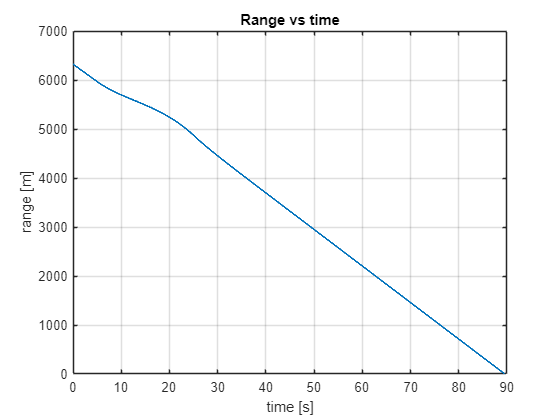

figure; plot(sim.t, sim.range, 'LineWidth',1.4);
grid on; xlabel('time [s]'); ylabel('range [m]');
title('Range vs time');

if SAVE_PLOT, saveas(gcf,'pn_range.png'); end

## Plot: LOS angle and LOS rate

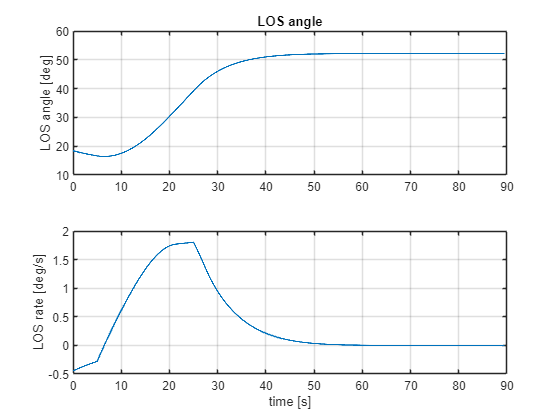

figure;
subplot(2,1,1);
plot(sim.t, rad2deg(sim.lambda), 'LineWidth', 1.2);
grid on; ylabel('LOS angle [deg]'); title('LOS angle');
subplot(2,1,2);
plot(sim.t, rad2deg(sim.lambda_dot), 'LineWidth', 1.2);
grid on; ylabel('LOS rate [deg/s]'); xlabel('time [s]');

if SAVE_PLOT, saveas(gcf,'pn_los.png'); end

## Plot: Commanded vs Applied lateral acceleration

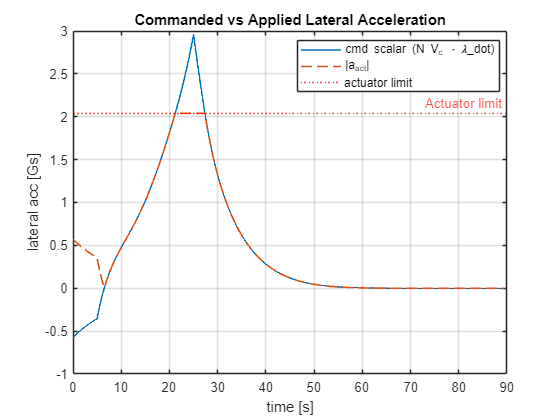

figure;
plot(sim.t, (s.N0*ones(size(sim.t))).*max(sim.Vc,0).*sim.lambda_dot/9.8, '-', 'LineWidth',1.2); hold on;
plot(sim.t, vecnorm(sim.a_act)/9.8, '--', 'LineWidth',1.2);
yline(s.a_max/9.8,'r:','Actuator limit');
grid on; xlabel('time [s]'); ylabel('lateral acc [Gs]');
legend('cmd scalar (N V_c \cdot \lambda\_dot)','|a_{act}|','actuator limit','Location','best');
title('Commanded vs Applied Lateral Acceleration');

if SAVE_PLOT, saveas(gcf,'pn_accel.png'); end

## Plot: Closing velocity and t_go estimate

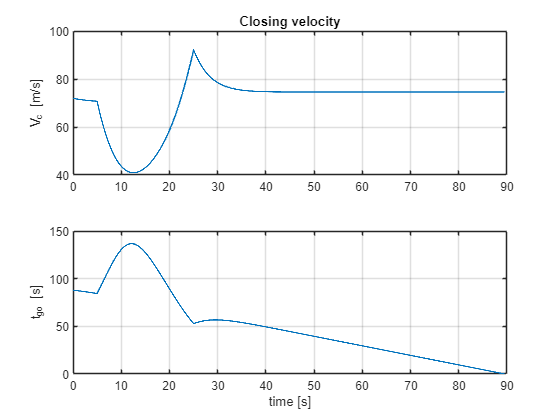

figure;
subplot(2,1,1);
plot(sim.t, sim.Vc, 'LineWidth', 1.2);
grid on; ylabel('V_c [m/s]'); title('Closing velocity');
subplot(2,1,2);
plot(sim.t, sim.tgo, 'LineWidth', 1.2);
grid on; ylabel('t_{go} [s]'); xlabel('time [s]');

if SAVE_PLOT, saveas(gcf,'pn_vc_tgo.png'); end

## Plot: ZEM perpendicular component (approx)

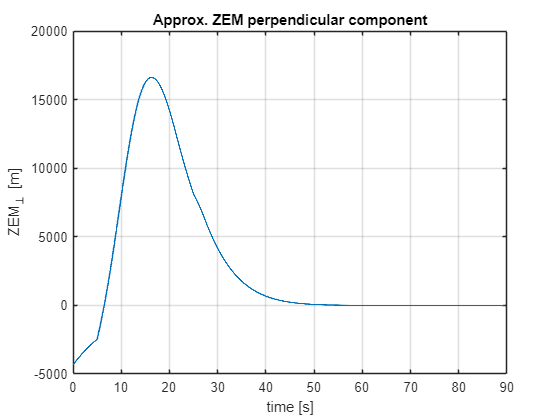

figure; plot(sim.t, sim.ZEM, 'LineWidth', 1.2);
grid on; xlabel('time [s]'); ylabel('ZEM_{\perp} [m]');
title('Approx. ZEM perpendicular component');

if SAVE_PLOT, saveas(gcf,'pn_zem.png'); end

## N-sweep: miss distance & intercept time

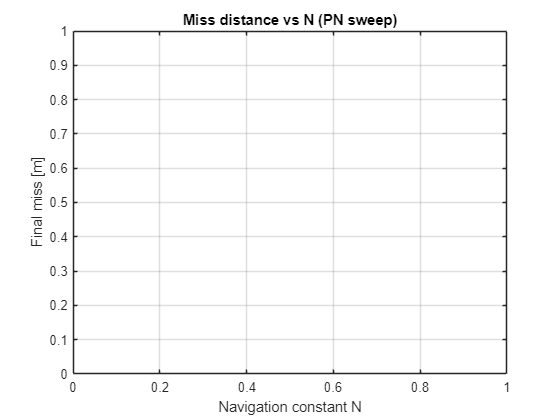

Ns = linspace(1.5, 6.0, 20);
miss_m = nan(size(Ns)); t_hit = nan(size(Ns)); hit = false(size(Ns));

for i = 1:numel(Ns)
    s_i = s; s_i.N0 = Ns(i);
    sim_i = pn_2d_sim(s_i);
    miss_m(i) = sim_i.miss_distance;
    t_hit(i)  = sim_i.impact_time;
    hit(i)    = sim_i.impact;
end

figure; plot(Ns, miss_m, 'o-','LineWidth',1.2);
grid on; xlabel('Navigation constant N'); ylabel('Final miss [m]');
title('Miss distance vs N (PN sweep)');

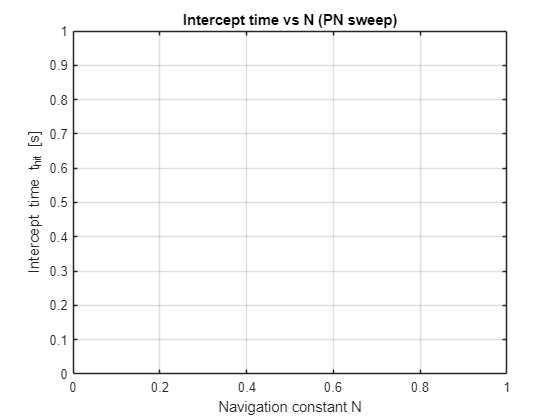

if SAVE_PLOT, saveas(gcf,'pn_sweep_miss_vs_N.png'); end

figure; plot(Ns, t_hit, 'o-','LineWidth',1.2);
grid on; xlabel('Navigation constant N'); ylabel('Intercept time t_{hit} [s]');
title('Intercept time vs N (PN sweep)');

if SAVE_PLOT, saveas(gcf,'pn_sweep_time_vs_N.png'); end

if any(hit)
    [~, idxBestLocal] = min(miss_m(hit));
    Ns_hit = Ns(hit); miss_hit = miss_m(hit); t_hit_hit = t_hit(hit);
    fprintf('Best N (among intercepts): N=%.3f, miss=%.3f m, t_hit=%.3f s\n', ...
        Ns_hit(idxBestLocal), miss_hit(idxBestLocal), t_hit_hit(idxBestLocal));
else
    fprintf('No intercepts in the tested N range.\n');
end

No intercepts in the tested N range.


## N-sweep: acceleration histories (`a_act` and n_c)

(Each run calls the same single-core pn_2d_sim function)

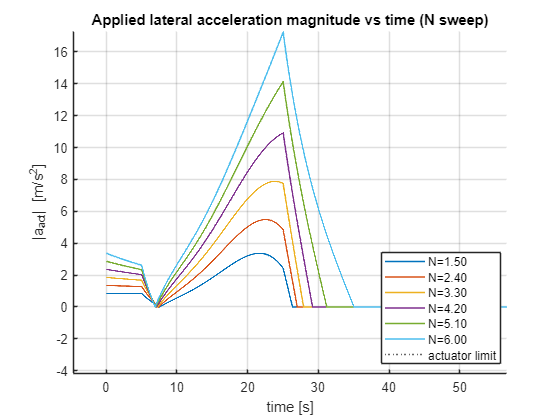

Ns_acc = linspace(1.5, 6.0, 6);
t_hist = cell(numel(Ns_acc),1);
aabs_hist = cell(numel(Ns_acc),1);
nc_hist = cell(numel(Ns_acc),1);

for i = 1:numel(Ns_acc)
    s_i = s; s_i.N0 = Ns_acc(i);
    si = pn_2d_sim(s_i);
    t_hist{i}   = si.t;
    aabs_hist{i}= vecnorm(si.a_act);
    nc_hist{i}  = (s_i.N0*ones(size(si.t))).*max(si.Vc,0).*si.lambda_dot;
end

figure; hold on;
for i = 1:numel(Ns_acc)
    plot(t_hist{i}, aabs_hist{i}, 'LineWidth', 1.2);
end
yline(s.a_max, ':', 'Actuator limit');
grid on; xlabel('time [s]'); ylabel('|a_{act}| [m/s^2]');
title('Applied lateral acceleration magnitude vs time (N sweep)');
legtxt = arrayfun(@(x) sprintf('N=%.2f', x), Ns_acc, 'UniformOutput', false);
legend([legtxt, {'actuator limit'}], 'Location','best');

xlim([-2.3 47.2])
ylim([-6.4 9.4])
legend("Position", [0.63893,0.64744,0.21429,0.26667])

xlim([-4.7 56.7])
ylim([-4.2 17.3])
legend("Position", [0.68,0.13315,0.21429,0.26667])

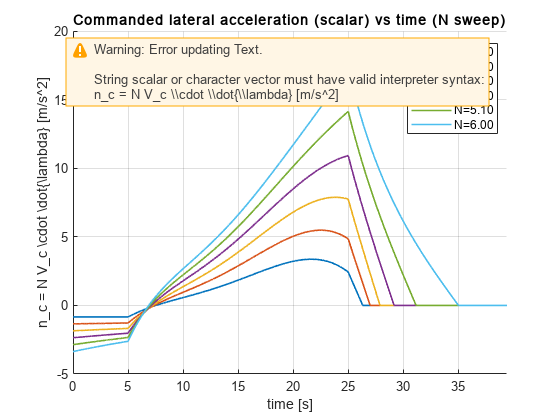

if SAVE_PLOT, saveas(gcf,'pn_sweep_aact_vs_time.png'); end

figure; hold on;
for i = 1:numel(Ns_acc)
    plot(t_hist{i}, nc_hist{i}, 'LineWidth', 1.2);
end
grid on; xlabel('time [s]'); ylabel('n_c = N V_c \cdot \dot{\lambda} [m/s^2]');
title('Commanded lateral acceleration (scalar) vs time (N sweep)');
legend(legtxt,'Location','best');

xlim([0.0 39.4])
ylim([-5.0 20.0])

if SAVE_PLOT, saveas(gcf,'pn_sweep_ncmd_vs_time.png'); end